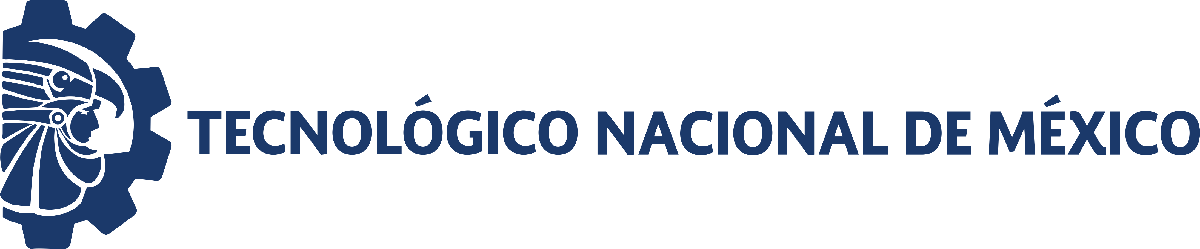                                 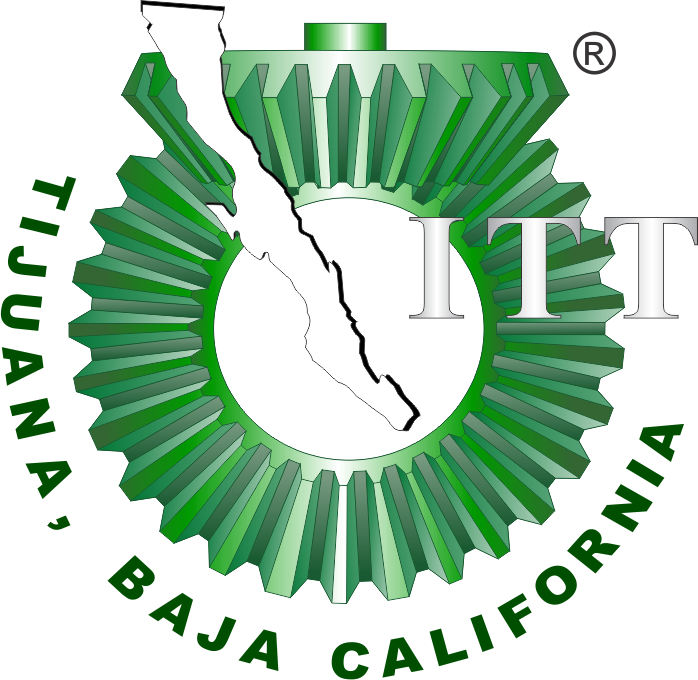

# Práctica 5: Sistema Muscoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general           

Nombre del alumno: LOPEZ LOPEZ SANTIAGO

Número de control: 22212260

Correo institucional: l22212260**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica5';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('Practica5/F(t)','Amplitude','1');
set_param('Practica5/F(t)','Period','10');
set_param('Practica5/F(t)','PulseWidth','10');
set_param('Practica5/F(t)','PhaseDelay','1');
x1 = sim(file,parameters);

Found algebraic loop containing: 
Practica5/PID Controller1/Parallel P Gain/Internal Parameters/Proportional Gain
Practica5/PID Controller1/Sum/Sum_PI/Sum
Practica5/Tratamiento
Practica5/Sum1 (algebraic variable)


writematrix( x1.F,'Signal.xlsx')

## Lazo Abierto 

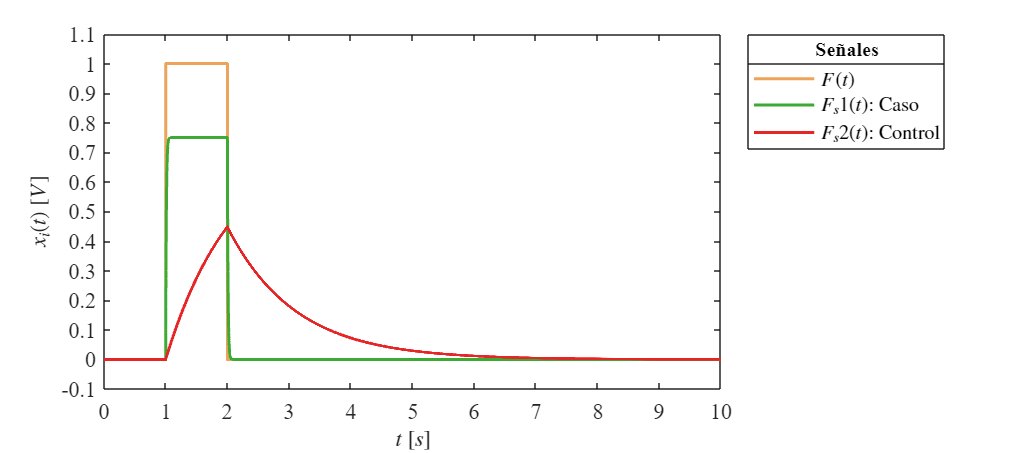

plotsignals(x1.t,x1.F,x1.Fs1,x1.Fs2)

## Lazo Cerrado

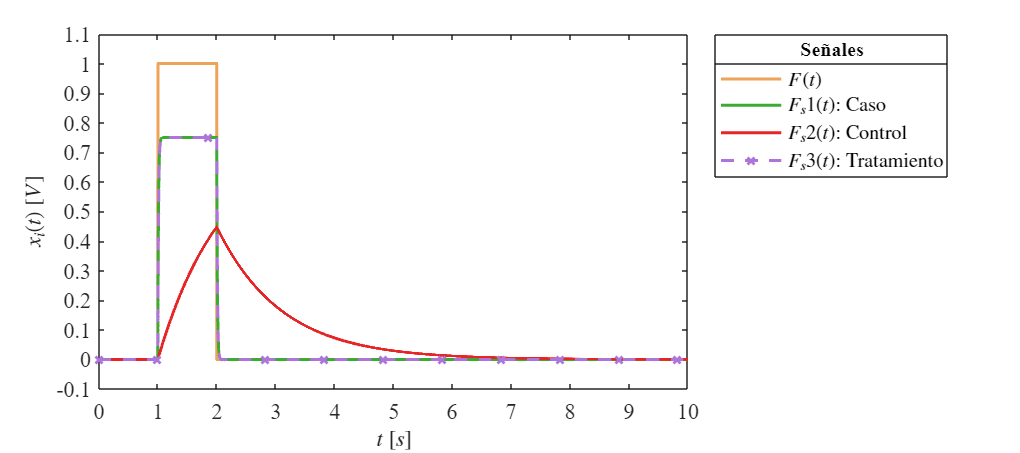

plotsignals2 (x1.t,x1.F,x1.Fs1,x1.Fs2,x1.Fs3)

## Funcion: Respuesta a las señales

function plotsignals (t,F,Fs1,Fs2,Signal)
    set(figure(),'Color',"W")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;   
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p,'LineWidth',1.5)
L = legend('$F(t)$','$F_s1(t)$: Caso','$F_s2(t)$: Control');
set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
title(L,'Señales','FontSize',10)

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    exportgraphics(gcf,['LazoAbierto.pdf'],'ContentType','vector')
    exportgraphics(gcf,['LazoAbierto.png'],'ContentType','vector')
end

function plotsignals2 (t,F,Fs1,Fs2,Fs3,Signal)
    set(figure(),'Color',"W")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;   
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'--x',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p,'LineWidth',1.5)
L = legend('$F(t)$','$F_s1(t)$: Caso','$F_s2(t)$: Control','$F_s3(t)$: Tratamiento');
set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
title(L,['Señales'],'FontSize',10)

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    
    exportgraphics(gcf,['LazoCerrado.pdf'],'ContentType','vector')
    exportgraphics(gcf,['LazoCerrado.png'],'ContentType','vector')
end
